# Author: DJP

This was a driver that should (emphasis on should) be able to stitch together recordings over different experimental contingencies. 4/20/2020

clear all;
close all;

## Get files, take user input, and make folder

[files, origDataPath] = ... % crucial distinction: files vs file (current)
    uigetfile('*.rhd', 'Select an RHD2000 Data File', 'MultiSelect', 'on');
% [file,origDataPath] = concat_Intan_RHD2000_files;
% make folder containing that files
if iscell(files)
    ts_label = files{1};
else
    ts_label = files;
    files = {files};
end
ts_label = ts_label(1:end-4);

% Getting using input about whether you are actually using all 32 channels,
% and whether you are using stereotrodes (as opposed to tetrodes)
is_32 = input('is this a 32 channel recording? (''1'' for yes, ''0'' for no )\n');
is_stereo = input('does the microdrive use stereotrodes? (''1'' for yes, ''0'' for no ) \n');

% Naming the directory/folder that will be named here
dataPath = fullfile(origDataPath,['DJPComb_' ts_label '_Kilosort']);
mkdir(dataPath)

addpath(dataPath)

## Build .dat, adc_data, and figure out when the context switches

Initialize adc data

board_adc = [];

% open raw.dat to write
dataFileName = fullfile(dataPath, 'raw_filtered.dat'); % [dataPath '\Kilosort_alldata\raw.dat'] % make .dat file
rawDataFID = fopen(dataFileName, 'w'); % open .dat file for writing

% Make a text file containing information about contingencies
contingenciesFid = fopen('contingencies.txt','w');

contingenciesFid = 13

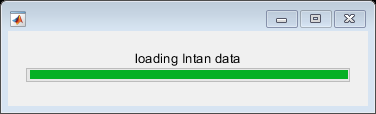


% sort according to filename. Not timestamp but filename
filearray = [];
for i = 1:length(files)
    filearray = [filearray dir(char(files(i)))];
end
[~, idx] = sort({filearray.date});
files = files(idx);

% make a waitbar!

f = waitbar(0, 'loading');
% I need to keep track of how long the recording is so that when the fem
% return is added, I can save the length. contextSwitch means the time at
% which the combined recording I'm doing is 

for i=1:length(files)
    % read
    read_Intan_RHD2000_file_MML_DJP(fullfile(filearray(i).folder,filearray(i).name),0);
    
    % bandpass filter
    datr = filter_datr(amplifier_data, frequency_parameters);

    % append to .dat files
    fwrite(rawDataFID, datr(:),'int16'); %     fwrite(fid1a, amplifier_data(:),'int16'); % append to .dat file
    
    % append to .mat file for adc_data
    if size(board_adc_data, 1) == 2
        board_adc_data = [NaN(1, size(board_adc_data, 2)); board_adc_data];
    end
    board_adc = [board_adc board_adc_data];
    

    % write your file
    fprintf(contingenciesFid, [filearray(i).name '\t' num2str(size(amplifier_data, 2)) '\n']);
    
    % update waitbar!
    waitbar(i/length(files), f, 'loading Intan data')
end


% Close raw data file and the contingencies.txt file
fclose(rawDataFID);
fclose(contingenciesFid);

% Close waitbar
close(f); 

Undefined function or variable 'waitbarFig'.


% Save adc data and adc sampling rate as adc_data.mat
adc_sr=frequency_parameters.board_adc_sample_rate;
save(fullfile(dataPath, 'adc_data'), 'board_adc', 'adc_sr', '-v7.3')

## write params.py

paramspyFid = fopen(fullfile(dataPath, 'params.py'),'w');

dat_path = 'raw_filtered.dat';
n_channels_dat = string(length(amplifier_channels));
dtype = 'int16';
offset = 0;
sample_rate = string(frequency_parameters.amplifier_sample_rate);
hp_filtered = 'True';

fprintf(paramspyFid, 'dat_path = r''%s''\n', dat_path);
fprintf(paramspyFid, 'n_channels_dat = %s\n', n_channels_dat); %2d means two digit
fprintf(paramspyFid, 'dtype = ''%s''\n', dtype);
fprintf(paramspyFid, 'offset = 0\n');
fprintf(paramspyFid, 'sample_rate = %s.\n', sample_rate);
fprintf(paramspyFid, 'hp_filtered = %s\n', hp_filtered);

fclose(paramspyFid);
clear fid2 dat_path dtype offset hp_filtered 
clear amplifier_channels amplifier_data aux_input_channels aux_input_data ...
        board_dig_in_data board_dig_in_channels filename frequency_parameters ...
        notes reference_channel spike_triggers supply_voltage_channels supply_voltage_data ...
        t_amplifier t_aux_input t_dig t_supply_voltage

## Identify the right config files to copy in

copy master file example and standard config and then edit them

working_dir = 'C:\Users\Healey Lab\Documents\MATLAB\KS-analysis';
if      is_32 && ~is_stereo % if 32 chan tetrode
    ChannelMapFile_orig      = fullfile(working_dir, 'createChannelMapFile32.m');
elseif ~is_32 &&  is_stereo % 16 chan stereotrode
    ChannelMapFile_orig      = fullfile(working_dir, 'createChannelMapFile16stereo.m');
elseif  is_32 &&  is_stereo % 32 chan stereotrode
    % TODO
elseif ~is_32 && ~is_stereo % 16 chan tetrode
    ChannelMapFile_orig      = fullfile(working_dir, 'createChannelMapFile.m');    
end
master_file_example_orig = fullfile(working_dir, 'master_file_example_MOVEME.m');
StandardConfig_orig      = fullfile(working_dir, 'StandardConfig_MOVEME.m');

copyfile(ChannelMapFile_orig,       dataPath)
copyfile(master_file_example_orig,  dataPath)
copyfile(StandardConfig_orig,       dataPath)

if      is_32 && ~is_stereo % if 32 chan tetrode
    ChannelMapFile_pasted      = fullfile(dataPath, 'createChannelMapFile32.m');
elseif ~is_32 &&  is_stereo % 16 chan stereotrode
    ChannelMapFile_pasted      = fullfile(dataPath, 'createChannelMapFile16stereo.m');
elseif  is_32 &&  is_stereo % 32 chan stereotrode
    % TODO
elseif  ~is_32 && ~is_stereo% 16 chan tetrode
    ChannelMapFile_pasted      = fullfile(dataPath, 'createChannelMapFile.m');
end
master_file_example_pasted = fullfile(dataPath, 'master_file_example_MOVEME.m');
StandardConfig_pasted      = fullfile(dataPath, 'StandardConfig_MOVEME.m');

## Edit Standard Config File

https://www.mathworks.com/matlabcentral/answers/62986-how-to-change-a-specific-line-in-a-text-file

standardConfigFid = fopen(StandardConfig_pasted,'r');
i = 1;
tline = fgetl(standardConfigFid);
A{i} = tline;
while ischar(tline)
    i = i+1;
    tline = fgetl(standardConfigFid);
    A{i} = tline;
end
fclose(standardConfigFid);
% Change lines of .m file
A{1}  = sprintf('ops.GPU=1;');
A{2}  = sprintf('ops.parfor=1;');
A{7}  = sprintf('ops.fbinary = ''%s'';', dataFileName); % dataFileName = 'C:\Users\danpo\Documents\sorting\mdx 10 8 18\filename'
A{8}  = sprintf('ops.fproc = ''%s'';', fullfile(dataPath,'temp_wh.dat')); % dataPath = 'C:\Users\danpo\Documents\sorting\mdx 10 8 18\'
A{9}  = sprintf('ops.root = ''%s'';',dataPath);
A{11} = sprintf('ops.fs = %s;',sample_rate);
A{12} = sprintf('ops.NchanTOT = %s;', n_channels_dat);
A{14} = sprintf('ops.Nfilt = 32;');
A{47} = sprintf('ops.mergeT           = .08;');
A{48} = sprintf('ops.splitT           = .12;');
A{51} = sprintf('ops.initialize      = ''fromData'';');
A{52} = sprintf('ops.spkTh           = -5;');

if is_32
    num_active_chan = 32;
else
    num_active_chan = 16;
end

A{13} = sprintf('ops.Nchan = %s;', string(num_active_chan)); % it's here. This is ground zero.
A{14} = sprintf('ops.Nfilt = %s;',  string(str2num(n_channels_dat) * 2));% number of clusters to use (2-4 times more than Nchan, should be a multiple of 32)   
A{15} = sprintf('ops.nNeighPC = %s; % visualization only (Phy): number of channnels to mask the PCs, leave empty to skip (12)', string(12));
A{16} = sprintf('ops.nNeigh = %s; % visualization only (Phy): number of neighboring templates to retain projections of (16)', string(num_active_chan));

A{24} = sprintf('ops.chanMap = ''%s'';',  fullfile(dataPath, 'chanMap.mat'));

% Write cell A into txt
standardConfigFid = fopen(StandardConfig_pasted, 'w');
for i = 1:numel(A)
    if A{i+1} == -1
        fprintf(standardConfigFid,'%s', A{i});
        break
    else
        fprintf(standardConfigFid,'%s\n', A{i});
    end
end
fclose(standardConfigFid);

## Edit ChannelMap

fid4 = fopen(ChannelMapFile_pasted,'r');
i = 1;
tline = fgetl(fid4);
B{i} = tline;
while ischar(tline)
    i = i+1;
    tline = fgetl(fid4);
    B{i} = tline;
end
fclose(fid4);
B{3} = sprintf('Nchannels = %s;', n_channels_dat);
B{6} = sprintf('pathToYourConfigFile = ''%s'';', dataPath);
B{11} = sprintf('fs = %s;', sample_rate);
if strcmp(n_channels_dat, '16')
    B{17} = sprintf('connected = logical(ones(16,1));');
    if is_stereo % if using stereotrodes,
        B{39} = sprintf('all_stereos = all_stereos-8;');
    else
        B{39} = sprintf('all_tetrodes = all_tetrodes-8;');
    end
end
B{48} = sprintf('save(''%s'', ...',  fullfile(dataPath, 'chanMap.mat'));

% Write cell B into .txt
fid4 = fopen(ChannelMapFile_pasted, 'w');
for i = 1:numel(B)
    if B{i+1} == -1
        fprintf(fid4,'%s', B{i});
        break
    else
        fprintf(fid4,'%s\n', B{i});
    end
end
fclose(fid4);

## Edit the master file

fid5 = fopen(master_file_example_pasted,'r');
i = 1;
tline = fgetl(fid5);
C{i} = tline;
while ischar(tline)
    i = i+1;
    tline = fgetl(fid5);
    C{i} = tline;
end
fclose(fid5);
% Change lines of .m file
C{3} = sprintf('addpath(genpath(''C:\\KiloSort-master''))'); % path to LOCAL kilosort folder

C{6} = sprintf('pathToYourConfigFile = ''%s''; ', dataPath);
% C{24} = sprintf('rez = merge_posthoc2(rez);', dataPath);

% Write cell C into txt
fid5 = fopen(master_file_example_pasted, 'w');
for i = 1:numel(C)
    if C{i+1} == -1
        fprintf(fid5,'%s', C{i});
        break
    else
        fprintf(fid5,'%s\n', C{i});
    end
end
fclose(fid5);

fclose('all');

## Go

Time   0s. Loading raw data... 
Time  39s. Channel-whitening filters computed. 
Time  39s. Loading raw data and applying filters... 
Time 154.81. Whitened data written to disk... 
Time 154.81. Preprocessing complete!
Starting parallel pool (parpool) using the 'local' profile ...
connected to 8 workers.
Time 173s. Optimizing templates ...
Time 174.63, batch 381/33948, mu 16.74, neg-err 19142.517122, NTOT 73859, n100 0, n200 0, n300 0, n400 0


Time 176.30, batch 781/33948, mu 17.32, neg-err 894462.572200, NTOT 161846, n100 0, n200 0, n300 0, n400 0


Time 177.85, batch 1181/33948, mu 19.98, neg-err 947153.717151, NTOT 259103, n100 0, n200 0, n300 0, n400 0


Time 179.35, batch 1581/33948, mu 19.60, neg-err 815852.871283, NTOT 369951, n100 0, n200 0, n300 0, n400 0


Time 180.89, batch 1981/33948, mu 20.43, neg-err 780538.626700, NTOT 490324, n100 0, n200 0, n300 0, n400 0


Time 182.36, batch 2381/33948, mu 24.29, neg-err 671438.670640, NTOT 620350, n100 0, n200 0, n300 0, n400 0


Time 183.82, batch 2781/33948, mu 23.63, neg-err 625123.970139, NTOT 750831, n100 0, n200 0, n300 0, n400 0


Time 185.38, batch 3181/33948, mu 22.90, neg-err 554954.830567, NTOT 887653, n100 0, n200 0, n300 0, n400 0


Time 186.97, batch 3581/33948, mu 22.88, neg-err 498541.331490, NTOT 1023059, n100 0, n200 0, n300 0, n400 0


Time 188.54, batch 3981/33948, mu 22.31, neg-err 456878.733488, NTOT 1159112, n100 0, n200 0, n300 0, n400 0


Time 190.06, batch 4381/33948, mu 22.38, neg-err 576065.832879, NTOT 1296698, n100 0, n200 0, n300 0, n400 0


Time 191.51, batch 4781/33948, mu 21.77, neg-err 531479.634060, NTOT 1422145, n100 1, n200 1, n300 1, n400 1


Time 192.96, batch 5181/33948, mu 21.55, neg-err 497722.645727, NTOT 1548086, n100 1, n200 1, n300 1, n400 1


Time 194.39, batch 5581/33948, mu 21.80, neg-err 509544.067535, NTOT 1657273, n100 1, n200 1, n300 1, n400 1


Time 194.70, batch 5641/33948, mu 22.76, neg-err 504497.527235, NTOT 1674216, n100 1, n200 1, n300 1, n400 1


Time 196.11, batch 6041/33948, mu 29.01, neg-err 503414.288096, NTOT 278051, n100 119, n200 119, n300 119, n400 119


Time 197.50, batch 6441/33948, mu 29.60, neg-err 467454.583820, NTOT 283219, n100 102, n200 102, n300 102, n400 102


Time 198.90, batch 6841/33948, mu 30.75, neg-err 463398.090264, NTOT 309287, n100 102, n200 102, n300 102, n400 102


Time 200.40, batch 7241/33948, mu 30.85, neg-err 452799.174172, NTOT 339316, n100 106, n200 106, n300 106, n400 106


Time 201.88, batch 7641/33948, mu 25.75, neg-err 413450.556826, NTOT 211775, n100 0, n200 0, n300 0, n400 0


Time 203.36, batch 8041/33948, mu 26.82, neg-err 405705.900119, NTOT 219264, n100 0, n200 0, n300 0, n400 0


Time 204.79, batch 8441/33948, mu 28.09, neg-err 386218.287296, NTOT 224935, n100 0, n200 0, n300 0, n400 0


Time 206.16, batch 8841/33948, mu 28.33, neg-err 384880.692853, NTOT 227269, n100 0, n200 0, n300 0, n400 0


Time 207.49, batch 9241/33948, mu 25.12, neg-err 384581.674235, NTOT 174165, n100 0, n200 0, n300 0, n400 0


Time 208.84, batch 9641/33948, mu 24.93, neg-err 381443.173355, NTOT 176011, n100 0, n200 0, n300 0, n400 0


Time 210.22, batch 10041/33948, mu 24.98, neg-err 293990.868969, NTOT 176280, n100 0, n200 0, n300 0, n400 0


Time 211.57, batch 10441/33948, mu 24.79, neg-err 293796.822476, NTOT 182198, n100 0, n200 0, n300 0, n400 0


Time 212.95, batch 10841/33948, mu 27.19, neg-err 290041.715459, NTOT 168299, n100 0, n200 0, n300 0, n400 0


Time 214.43, batch 11241/33948, mu 28.05, neg-err 296330.239883, NTOT 180399, n100 0, n200 0, n300 0, n400 0


Time 214.75, batch 11301/33948, mu 28.63, neg-err 296184.382879, NTOT 182548, n100 0, n200 0, n300 0, n400 0


Time 216.24, batch 11701/33948, mu 27.44, neg-err 296750.099759, NTOT 183635, n100 0, n200 0, n300 0, n400 0


Time 217.70, batch 12101/33948, mu 27.41, neg-err 329759.624831, NTOT 188183, n100 0, n200 0, n300 0, n400 0


Time 219.15, batch 12501/33948, mu 28.51, neg-err 298132.197299, NTOT 191095, n100 0, n200 0, n300 0, n400 0


Time 220.50, batch 12901/33948, mu 28.87, neg-err 298148.636197, NTOT 192736, n100 0, n200 0, n300 0, n400 0


Time 221.86, batch 13301/33948, mu 30.81, neg-err 312627.107185, NTOT 178079, n100 0, n200 0, n300 0, n400 0


Time 223.22, batch 13701/33948, mu 32.56, neg-err 315032.939776, NTOT 179699, n100 0, n200 0, n300 0, n400 0


Time 224.59, batch 14101/33948, mu 34.30, neg-err 320395.382820, NTOT 182166, n100 0, n200 0, n300 0, n400 0


Time 225.96, batch 14501/33948, mu 35.06, neg-err 319481.365837, NTOT 183930, n100 0, n200 0, n300 0, n400 0


Time 227.33, batch 14901/33948, mu 30.43, neg-err 317184.943459, NTOT 173418, n100 0, n200 0, n300 0, n400 0


Time 228.73, batch 15301/33948, mu 31.32, neg-err 315527.930056, NTOT 173901, n100 0, n200 0, n300 0, n400 0


Time 230.08, batch 15701/33948, mu 32.53, neg-err 289940.075141, NTOT 170335, n100 0, n200 0, n300 0, n400 0


Time 231.44, batch 16101/33948, mu 32.95, neg-err 288266.839721, NTOT 167686, n100 0, n200 0, n300 0, n400 0


Time 232.80, batch 16501/33948, mu 39.65, neg-err 290016.140153, NTOT 142678, n100 256, n200 256, n300 256, n400 256


Time 234.15, batch 16901/33948, mu 40.00, neg-err 275411.613386, NTOT 144929, n100 284, n200 284, n300 284, n400 284


Time 234.46, batch 16961/33948, mu 40.59, neg-err 275508.721232, NTOT 145328, n100 284, n200 284, n300 284, n400 284


Time 235.82, batch 17361/33948, mu 35.15, neg-err 274752.403449, NTOT 145666, n100 0, n200 0, n300 0, n400 0


Time 237.17, batch 17761/33948, mu 35.74, neg-err 213148.667252, NTOT 145989, n100 0, n200 0, n300 0, n400 0


Time 238.53, batch 18161/33948, mu 35.59, neg-err 192498.358466, NTOT 147088, n100 0, n200 0, n300 0, n400 0


Time 239.89, batch 18561/33948, mu 35.96, neg-err 185923.384868, NTOT 146736, n100 0, n200 0, n300 0, n400 0


Time 241.28, batch 18961/33948, mu 25.86, neg-err 195569.570673, NTOT 144218, n100 0, n200 0, n300 0, n400 0


Time 242.80, batch 19361/33948, mu 26.47, neg-err 196518.411901, NTOT 145438, n100 0, n200 0, n300 0, n400 0


Time 244.39, batch 19761/33948, mu 26.93, neg-err 199680.533341, NTOT 144867, n100 0, n200 0, n300 0, n400 0


Time 245.88, batch 20161/33948, mu 27.22, neg-err 202588.114440, NTOT 146087, n100 0, n200 0, n300 0, n400 0


Time 247.37, batch 20561/33948, mu 30.73, neg-err 202629.445012, NTOT 143464, n100 0, n200 0, n300 0, n400 0


Time 248.76, batch 20961/33948, mu 31.49, neg-err 203069.432059, NTOT 141842, n100 0, n200 0, n300 0, n400 0


Time 250.12, batch 21361/33948, mu 32.00, neg-err 243668.079338, NTOT 141994, n100 0, n200 0, n300 0, n400 0


Time 251.45, batch 21761/33948, mu 32.43, neg-err 245712.494544, NTOT 140954, n100 0, n200 0, n300 0, n400 0


Time 252.79, batch 22161/33948, mu 33.38, neg-err 244800.738487, NTOT 122197, n100 0, n200 0, n300 0, n400 0


Time 254.17, batch 22561/33948, mu 34.54, neg-err 242461.775113, NTOT 120771, n100 0, n200 0, n300 0, n400 0


Time 254.47, batch 22621/33948, mu 34.77, neg-err 242394.194728, NTOT 120672, n100 0, n200 0, n300 0, n400 0


Time 255.83, batch 23021/33948, mu 29.88, neg-err 242028.356885, NTOT 114864, n100 0, n200 0, n300 0, n400 0


Time 257.23, batch 23421/33948, mu 30.35, neg-err 194515.513399, NTOT 114795, n100 0, n200 0, n300 0, n400 0


Time 258.62, batch 23821/33948, mu 31.33, neg-err 182622.803522, NTOT 114192, n100 0, n200 0, n300 0, n400 0


Time 260.01, batch 24221/33948, mu 31.84, neg-err 175257.999949, NTOT 115143, n100 0, n200 0, n300 0, n400 0


Time 261.38, batch 24621/33948, mu 29.60, neg-err 155463.444389, NTOT 114573, n100 0, n200 0, n300 0, n400 0


Time 262.75, batch 25021/33948, mu 30.19, neg-err 152492.728025, NTOT 112954, n100 0, n200 0, n300 0, n400 0


Time 264.13, batch 25421/33948, mu 31.73, neg-err 143060.795497, NTOT 112574, n100 0, n200 0, n300 0, n400 0


Time 265.52, batch 25821/33948, mu 32.24, neg-err 139297.330956, NTOT 112448, n100 0, n200 0, n300 0, n400 0


Time 266.94, batch 26221/33948, mu 28.04, neg-err 139072.174769, NTOT 109861, n100 0, n200 0, n300 0, n400 0


Time 268.32, batch 26621/33948, mu 30.35, neg-err 138451.646259, NTOT 109193, n100 0, n200 0, n300 0, n400 0


Time 269.68, batch 27021/33948, mu 32.38, neg-err 106524.753282, NTOT 109064, n100 0, n200 0, n300 0, n400 0


Time 271.07, batch 27421/33948, mu 33.04, neg-err 106089.556474, NTOT 110401, n100 0, n200 0, n300 0, n400 0


Time 272.56, batch 27821/33948, mu 32.27, neg-err 104527.180851, NTOT 107302, n100 0, n200 0, n300 0, n400 0


Time 274.11, batch 28221/33948, mu 33.61, neg-err 105575.046671, NTOT 105278, n100 0, n200 0, n300 0, n400 0


Time 274.45, batch 28281/33948, mu 34.68, neg-err 105497.658741, NTOT 104785, n100 0, n200 0, n300 0, n400 0


Time 275.94, batch 28681/33948, mu 32.78, neg-err 105384.769260, NTOT 101967, n100 101, n200 101, n300 101, n400 101


Time 277.39, batch 29081/33948, mu 33.30, neg-err 156094.632013, NTOT 98941, n100 84, n200 84, n300 84, n400 84


Time 278.76, batch 29481/33948, mu 34.61, neg-err 165355.688030, NTOT 95692, n100 67, n200 67, n300 67, n400 67


Time 280.12, batch 29881/33948, mu 35.88, neg-err 174547.014575, NTOT 93193, n100 60, n200 60, n300 60, n400 60


Time 281.48, batch 30281/33948, mu 35.47, neg-err 183760.665369, NTOT 91781, n100 190, n200 190, n300 190, n400 190


Time 282.83, batch 30681/33948, mu 36.29, neg-err 184979.376791, NTOT 90216, n100 169, n200 169, n300 169, n400 169


Time 284.16, batch 31081/33948, mu 37.39, neg-err 190544.518128, NTOT 88667, n100 127, n200 127, n300 127, n400 127


Time 285.52, batch 31481/33948, mu 37.45, neg-err 190761.210873, NTOT 86044, n100 123, n200 123, n300 123, n400 123


Time 286.95, batch 31881/33948, mu 37.33, neg-err 191036.503384, NTOT 82657, n100 0, n200 0, n300 0, n400 0


Time 288.29, batch 32281/33948, mu 37.59, neg-err 191705.255741, NTOT 84176, n100 0, n200 0, n300 0, n400 0


Time 289.62, batch 32681/33948, mu 38.11, neg-err 216187.635049, NTOT 82866, n100 0, n200 0, n300 0, n400 0


Time 290.97, batch 33081/33948, mu 38.81, neg-err 214812.241722, NTOT 80215, n100 0, n200 0, n300 0, n400 0


Time 292.33, batch 33481/33948, mu 35.64, neg-err 215554.179637, NTOT 81328, n100 106, n200 106, n300 106, n400 106


Time 293.72, batch 33881/33948, mu 37.08, neg-err 245949.122401, NTOT 85134, n100 108, n200 108, n300 108, n400 108


Time 294.03, batch 33941/33948, mu 37.08, neg-err 246214.690002, NTOT 85337, n100 108, n200 108, n300 108, n400 108


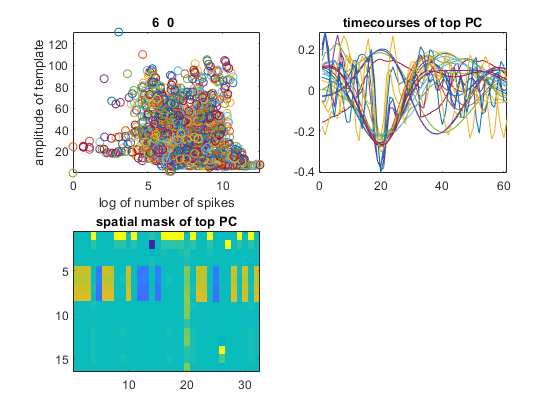

Time 294s. Running the final template matching pass...
Time 365.80, batch 5601/5658,  NTOT 149344


run(ChannelMapFile_pasted)
run(master_file_example_pasted) % master_file_example_MOVEME

% If you run into this error, it's because of the line that changes NChan % in the config file to 32 or 16. It should be dynamic. NChanTOT is % always 32 though. (search 'ground zero' to find it) Error using + Matrix dimensions must agree.

Error in preprocessData (line 163) CC = CC + (datr' * datr)/NT;

Error in master_file_example_MOVEME (line 19) [rez, DATA, uproj] = preprocessData(ops); % preprocess data and extract spikes for initialization